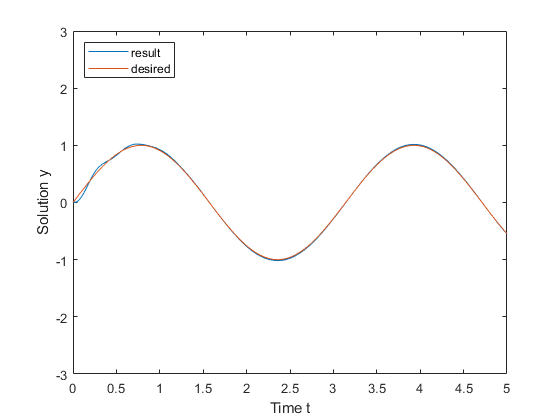

close all; clear all;

lags = [0.1];
tspan = [0 5];
sol = dde23(@ddefun, lags, @history, tspan);

plot(sol.x,sol.y(1,:)); hold on;
plot(sol.x,sin(2*sol.x))
xlabel('Time t');
ylabel('Solution y');
legend('result','desired','Location','NorthWest');
ylim([-3 3])